% This script analytically calculated the SF and BM 
% distribution about the wing, for Remi

% First, we must define some masses, namely: wing
% structural mass, fuel mass, engine mass, and u/c mass

wing_mass = 1335.5; % kg
uc_mass = 65; % kg
engine_mass = 3323; % kg 
fuel_mass = 5563.8; % kg

% Next, define where these masses are distributed from:

wing_length = 12.165 - 0; % wing: 0 - 12.165 
uc_length = 0.330 - 0; % u/c: 0 - 0.330
engine_length = 0; % engine: Point at 3.18
fuel_length = 10.95 - 0; % fuel: 0 - 10.95
engine_loc = 3.18;

% Now, find the loads per unit length:
wing_unit = wing_mass / wing_length;
uc_unit = uc_mass / uc_length;
engine_unit = engine_mass;
fuel_unit = fuel_mass / fuel_length;

% Now, start at the end of the wing and find the bending
% moments and shear forces analytically: 

% ----------------------------------
% A   B     C                D     E 

syms z;
% D-E
M_DE = -wing_unit * z * (z/2);
M_DE = M_DE * 9.81

$$M\_DE = -\frac{7578453444318465903\,z^{2}}{14073748835532800}$$


% C-D
M_CD = -wing_unit * z * (z/2)...
    -fuel_unit* (z-(wing_length-fuel_length)) * (z-(wing_length-fuel_length))/2;
M_CD = M_CD * 9.81

$$M\_CD = -\frac{981\,\left(\frac{37092\,z}{73}-\frac{2253339}{3650}\right)\,\left(z-\frac{243}{200}\right)}{200}-\frac{7578453444318465903\,z^{2}}{14073748835532800}$$


% B-C
M_BC = -wing_unit * z * (z/2)...
    -fuel_unit * (z-(wing_length-fuel_length)) * (z-(wing_length-fuel_length))/2 ...
    -engine_unit * (z-(wing_length-engine_loc));
M_BC = M_BC * 9.81

$$M\_BC = \frac{5857973811}{20000}-\frac{981\,\left(\frac{37092\,z}{73}-\frac{2253339}{3650}\right)\,\left(z-\frac{243}{200}\right)}{200}-\frac{7578453444318465903\,z^{2}}{14073748835532800}-\frac{3259863\,z}{100}$$


% A-B
M_AB = -wing_unit * z * (z/2)...
    - fuel_unit * (z-(wing_length-fuel_length)) * (z-(wing_length-fuel_length))/2 ...
    - engine_unit * (z-(wing_length-engine_loc)) ...
    - uc_unit * (z-(wing_length-uc_length)) * (z-(wing_length-uc_length))/2;
M_AB = M_AB * 9.81

$$M\_AB = \frac{5857973811}{20000}-\frac{981\,\left(\frac{6500\,z}{33}-\frac{51285}{22}\right)\,\left(z-\frac{2367}{200}\right)}{200}-\frac{981\,\left(\frac{37092\,z}{73}-\frac{2253339}{3650}\right)\,\left(z-\frac{243}{200}\right)}{200}-\frac{7578453444318465903\,z^{2}}{14073748835532800}-\frac{3259863\,z}{100}$$


% Now, find the maximum BM:

Max_BM = double(subs(M_AB,z,wing_length))

Max_BM = -4.8229e+05

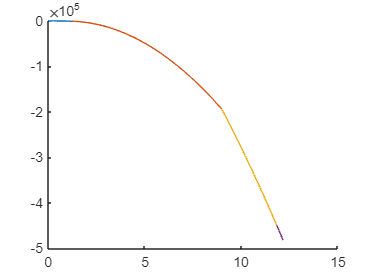


% Plot the BM distribution: N.B. This is for the left wing:

figure
hold on
fplot(M_DE,[0 wing_length-fuel_length])
fplot(M_CD,[wing_length-fuel_length wing_length-engine_loc])
fplot(M_BC,[wing_length-engine_loc wing_length-uc_length])
fplot(M_AB,[wing_length-uc_length wing_length])
hold off